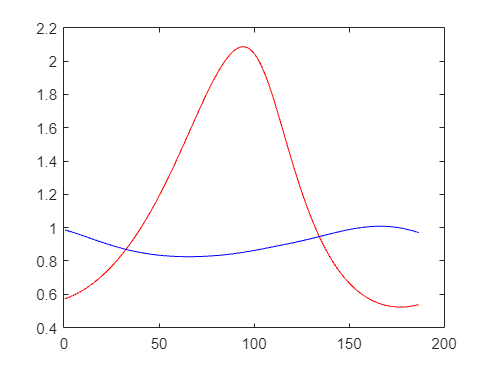

clear; clc
velocity = 25;      L = 187;        init_weight = 0;        n_ca3_bio = 200;    n_ca3_map = 400;
inductions = [1, L/2];
[synaptic_weight_map, list_pot_map, list_dep_map, ca3_peak_locations_map] = ...
    Sim_CA3CA1_map(velocity, inductions, init_weight, L, n_ca3_map);
[synaptic_weight, list_pot, list_dep, ca3_peak_locations] = ...
    Sim_CA3CA1_Romani(velocity, inductions, init_weight, L, n_ca3_bio);

pot_r = list_pot(1, :);
dep_r = list_dep(1, :);     
%
plot(ca3_peak_locations, pot_r, "r")
hold on
plot(ca3_peak_locations, dep_r, "b")
hold off

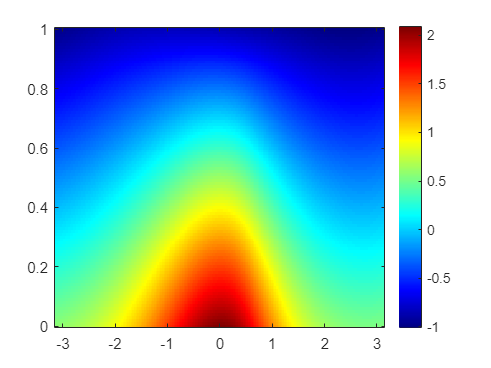

%}
figure
ind_pos = L/2;
init_weights = 0:0.01:1;
init_weights = init_weights';
romani_plasticity = pot_r .* (1 - init_weights) - dep_r .* init_weights;
%romani_plasticity = max(min(romani_plasticity, 1), -1)
time_axis = (ca3_peak_locations_map - ind_pos) / L * 2*pi;
imagesc(time_axis, init_weights, romani_plasticity)
colormap(jet)
colorbar
set(gca,'YDir','normal')